## **Clean up variables and RoadRunner**

% Check if a variable called "rrApp" exists in workspace
if exist("rrApp", "var") 
     % Check if it's actually a RoadRunner object (not something else)
    if class(rrApp) == "roadrunner"
        rrApp.close(); % Close the RoadRunner window properly
    end
end

% Check if rrSim exists (the simulation connection object)
if exist("rrSim", "var")
    delete(rrSim);  % Disconnect and delete the simulation object
end

close all;
clear;
setenv("NO_PROXY", "localhost");  % Tell MATLAB not to use a proxy 
                                  % server for localhost connections
                                  % (fixes connection issues between
                                  % MATLAB and RoadRunner)



## Launch RoadRunner from Matlab 

%Launch RoadRunner 
rrProj = "C:\Users\user\OneDrive\Documents\Test 1";
rrApp = roadrunner(rrProj);

%Check launch status 
status(rrApp)

ans = struct with fields:
     Project: [1×1 struct]
       Scene: [1×1 struct]
    Scenario: []



%Open Scene
openScene(rrApp,"C:\Users\user\OneDrive\Documents\Test 1\Scenes\UNM_FrontJunct-V2.rrscene");

%Open Scenario 
openScenario(rrApp,"C:\Users\user\OneDrive\Documents\Test 1\Scenarios\UNM_Eg-Test2.rrscenario");

%Create scenario simulation objs to manage simulations 
rrSim = createSimulation(rrApp);
%Enable data logging 
set(rrSim,Logging="on")

%Set scenario to run at step size of 0.1s = Frame rate of simulation  
Ts = 0.1;
rrSim.set("StepSize", Ts);

% Setup everything before simulation starts 
UNM_Setup(rrApp,rrSim);

Loading UNM bus objects...
  [OK] BusActorRuntime loaded
  [OK] BusVehicleRuntime loaded
  [OK] BusRuntimeTurnConfiguration loaded
  [OK] BusBulbConfiguration loaded
  [OK] BusSignalConfiguration loaded
  [OK] BusSignalHead loaded
  [OK] BusTrafficSignalRuntime loaded

All UNM bus objects loaded successfully!
You can now open UNM_TrafficSignalFollower.slx




% Open the Simulink model
model_name = "C:\Users\user\OneDrive\Documents\MATLAB\Summer_Intern\Simulink\UNM_TrafficSignalFollower.slx";
open_system(model_name)

% Load Trained RL agent 
load('trained_agent_ACC.mat', 'agent');
agent.UseExplorationPolicy = false;

agentBlockPath = 'UNM_TrafficSignalFollower/RL Agent';   
set_param(agentBlockPath, 'Agent', 'agent');

## Start Simulation

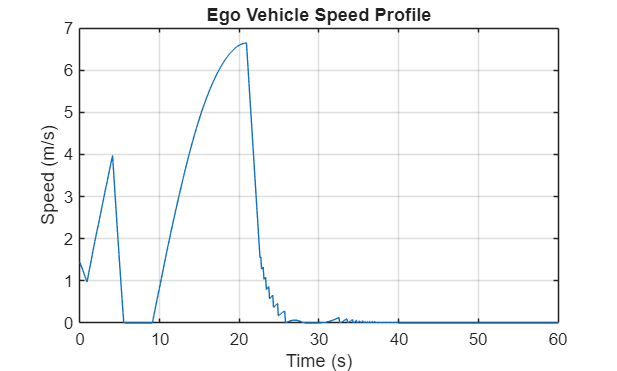

% Start simulation
set(rrSim, SimulationCommand="Start")

% Wait until RoadRunner Scenario simulation is finished
while strcmp(rrSim.get("SimulationStatus"),"Running")
  pause(1)
end

% After simulation stops
rrLog = rrSim.get("SimulationLog");

% Get velocity of actor 1
velocityLog = get(rrLog, 'Velocity', 'ActorID', 1);
timeLog = [velocityLog.Time];

% Calculate speed magnitude at each timestep
speedValues = arrayfun(@(x) norm(x.Velocity), velocityLog);

% Plot
figure
plot(timeLog, speedValues);
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Ego Vehicle Speed Profile');
grid on;